Cargamos el dataset `datos_pima` dentro de la carpeta datasets.

data = load('datasets\datos_pima.mat');
P = data.P; % Patrones de entrada
T = data.T; % Salidas deseadas

% Creación del perceptón simple
red = newp(minmax(P),1);

% Entrenamiento de la red
red = train(red, P, T);

% Obtenemos las salidas para los patrones de entrenamiento
S = sim(red, P);

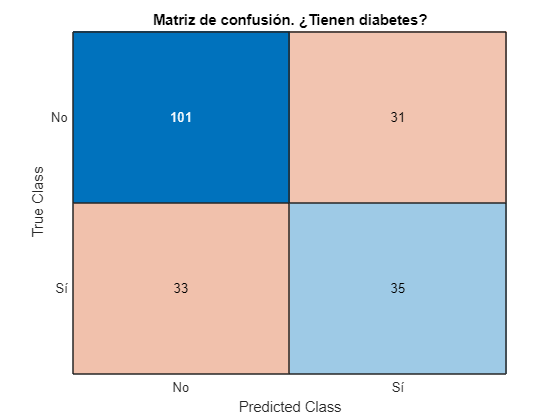

C = confusionmat(T,S);
classLabels = categorical({'No'; 'Sí'});
cm = confusionchart(C, classLabels);
cm.Title = 'Matriz de confusión. ¿Tienen diabetes?';